# Standard Display

## Introduction

## Learning Objectives

## State Space Representation of Model

g=9.81;    % m/s^2   gravitational constant
m=0.1;     % mass in kg
T=@(t,x,v)m*g;      % Thrust chosen to compensate for gravity
tspan=[0,5];        % time span of interest

F=@(t,z) g-T(t,z(1),z(2))/m;    % total force , thrust and gravity, acting on quadcopter

z0=[0;0];   % initial position in m and initial velocity in m/s
z_desired=-1;  v_desired=0;
kp=2;kd=2.5;

F4=@(t,z)F(t,z)+kp*(z_desired-z(1))+kd*(v_desired-z(2));  % Force including Control (PD+FF)
dzdt=@(t,z)[z(2);F4(t,z)];
[t,z]=ode45(dzdt,tspan,z0);



## Standard Display

% plot(t,z,'*');grid on;axis([0,5,-2,0]);xlabel('time');ylabel('altitude');title('Hover Example');legend('z(t)','v(t)')
% 
% 
figure('Name','Hover Example'); 
fprintf('Hover Example');

Hover Example

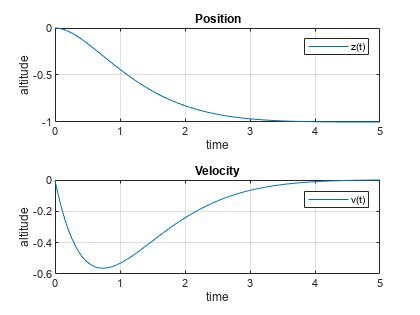

tiledlayout(2,1);
ax1=nexttile;
plot(ax1,t,z(:,1));grid on;xlabel('time');ylabel('altitude');title(ax1,'Position');legend('z(t)')

ax2=nexttile;
plot(ax2,t,z(:,2));grid on;xlabel('time');ylabel('altitude');title(ax2,'Velocity');legend('v(t)')